clc, clear, close all
rng(200)

data = readtable('CTG.csv');
data

data = 2126×37 table
    b     e      LBE    LB     AC    FM     UC    ASTV    MSTV    ALTV    MLTV    DL    DS    DP    DR    Width    Min    Max    Nmax    Nzeros    Mode    Mean    Median    Variance    Tendency    A    B    C    D    E    AD    DE    LD    FS    SUSP    CLASS    NSP
    _    ____    ___    

data(:, {'b','e', 'A', 'B', 'C', 'DE', 'E', 'AD', 'DE', 'LD', 'FS', 'SUSP', 'CLASS'}) = [];
data.LBE = normalize(data.LBE)

data = 2126×25 table
      LBE       LB     AC    FM     UC    ASTV    MSTV    ALTV    MLTV    DL    DS    DP    DR    Width    Min    Max    Nmax    Nzeros    Mode    Mean    Median    Variance    Tendency    D    NSP
    ________    ___    __    ___    __    ____    ____    ____    ____    __    __    __    __    _____    ___

data.LB = normalize(data.LB)

data = 2126×25 table
      LBE          LB       AC    FM     UC    ASTV    MSTV    ALTV    MLTV    DL    DS    DP    DR    Width    Min    Max    Nmax    Nzeros    Mode    Mean    Median    Variance    Tendency    D    NSP
    ________    ________    __    ___    __    ____    ____    ____    ____    __    __    __    __    _____    <

data.AC = normalize(data.AC)

data = 2126×25 table
      LBE          LB          AC       FM     UC    ASTV    MSTV    ALTV    MLTV    DL    DS    DP    DR    Width    Min    Max    Nmax    Nzeros    Mode    Mean    Median    Variance    Tendency    D    NSP
    ________    ________    ________    ___    __    ____    ____    ____    ____    __    __    __    __    _____</

data.FM = normalize(data.FM)

data = 2126×25 table
      LBE          LB          AC          FM       UC    ASTV    MSTV    ALTV    MLTV    DL    DS    DP    DR    Width    Min    Max    Nmax    Nzeros    Mode    Mean    Median    Variance    Tendency    D    NSP
    ________    ________    ________    ________    __    ____    ____    ____    ____    __    __    __    __    

data.UC = normalize(data.UC)

data = 2126×25 table
      LBE          LB          AC          FM          UC       ASTV    MSTV    ALTV    MLTV    DL    DS    DP    DR    Width    Min    Max    Nmax    Nzeros    Mode    Mean    Median    Variance    Tendency    D    NSP
    ________    ________    ________    ________    ________    ____    ____    ____    ____    __    __    __    __

data.ASTV = normalize(data.ASTV)

data = 2126×25 table
      LBE          LB          AC          FM          UC        ASTV      MSTV    ALTV    MLTV    DL    DS    DP    DR    Width    Min    Max    Nmax    Nzeros    Mode    Mean    Median    Variance    Tendency    D    NSP
    ________    ________    ________    ________    ________    _______    ____    ____    ____    __    __    __    __

data.MSTV = normalize(data.MSTV)

data = 2126×25 table
      LBE          LB          AC          FM          UC        ASTV        MSTV      ALTV    MLTV    DL    DS    DP    DR    Width    Min    Max    Nmax    Nzeros    Mode    Mean    Median    Variance    Tendency    D    NSP
    ________    ________    ________    ________    ________    _______    ________    ____    ____    __    __    __    <s

data.MLTV = normalize(data.MLTV)

data = 2126×25 table
      LBE          LB          AC          FM          UC        ASTV        MSTV      ALTV      MLTV       DL    DS    DP    DR    Width    Min    Max    Nmax    Nzeros    Mode    Mean    Median    Variance    Tendency    D    NSP
    ________    ________    ________    ________    ________    _______    ________    ____    _________    __    __    __

data.DL = normalize(data.DL)

data = 2126×25 table
      LBE          LB          AC          FM          UC        ASTV        MSTV      ALTV      MLTV          DL       DS    DP    DR    Width    Min    Max    Nmax    Nzeros    Mode    Mean    Median    Variance    Tendency    D    NSP
    ________    ________    ________    ________    ________    _______    ________    ____    _________    ________    __    

data.DS = normalize(data.DS)

data = 2126×25 table
      LBE          LB          AC          FM          UC        ASTV        MSTV      ALTV      MLTV          DL          DS        DP    DR    Width    Min    Max    Nmax    Nzeros    Mode    Mean    Median    Variance    Tendency    D    NSP
    ________    ________    ________    ________    ________    _______    ________    ____    _________    ________    _________</

data.Width = normalize(data.Width)

data = 2126×25 table
      LBE          LB          AC          FM          UC        ASTV        MSTV      ALTV      MLTV          DL          DS        DP    DR     Width     Min    Max    Nmax    Nzeros    Mode    Mean    Median    Variance    Tendency    D    NSP
    ________    ________    ________    ________    ________    _______    ________    ____    _________    ________    _________

data.Min = normalize(data.Min)

data = 2126×25 table
      LBE          LB          AC          FM          UC        ASTV        MSTV      ALTV      MLTV          DL          DS        DP    DR     Width       Min       Max    Nmax    Nzeros    Mode    Mean    Median    Variance    Tendency    D    NSP
    ________    ________    ________    ________    ________    _______    ________    ____    _________    ________    ____

data.Max = normalize(data.Max)

data = 2126×25 table
      LBE          LB          AC          FM          UC        ASTV        MSTV      ALTV      MLTV          DL          DS        DP    DR     Width       Min         Max       Nmax    Nzeros    Mode    Mean    Median    Variance    Tendency    D    NSP
    ________    ________    ________    ________    ________    _______    ________    ____    _________    ________    

data.Nmax = normalize(data.Nmax)

data = 2126×25 table
      LBE          LB          AC          FM          UC        ASTV        MSTV      ALTV      MLTV          DL          DS        DP    DR     Width       Min         Max         Nmax      Nzeros    Mode    Mean    Median    Variance    Tendency    D    NSP
    ________    ________    ________    ________    ________    _______    ________    ____    _________    ________    

data.Mode = normalize(data.Mode)

data = 2126×25 table
      LBE          LB          AC          FM          UC        ASTV        MSTV      ALTV      MLTV          DL          DS        DP    DR     Width       Min         Max         Nmax      Nzeros      Mode      Mean    Median    Variance    Tendency    D    NSP
    ________    ________    ________    ________    ________    _______    ________    ____    _________    ________   

data.Mean = normalize(data.Mean)

data = 2126×25 table
      LBE          LB          AC          FM          UC        ASTV        MSTV      ALTV      MLTV          DL          DS        DP    DR     Width       Min         Max         Nmax      Nzeros      Mode        Mean      Median    Variance    Tendency    D    NSP
    ________    ________    ________    ________    ________    _______    ________    ____    _________    ________

data.Median = normalize(data.Median)

data = 2126×25 table
      LBE          LB          AC          FM          UC        ASTV        MSTV      ALTV      MLTV          DL          DS        DP    DR     Width       Min         Max         Nmax      Nzeros      Mode        Mean       Median     Variance    Tendency    D    NSP
    ________    ________    ________    ________    ________    _______    ________    ____    _________    ________

data.Variance = normalize(data.Variance)

data = 2126×25 table
      LBE          LB          AC          FM          UC        ASTV        MSTV      ALTV      MLTV          DL          DS        DP    DR     Width       Min         Max         Nmax      Nzeros      Mode        Mean       Median     Variance    Tendency    D    NSP
    ________    ________    ________    ________    ________    _______    ________    ____    _________    ________

data

data = 2126×25 table
      LBE          LB          AC          FM          UC        ASTV        MSTV      ALTV      MLTV          DL          DS        DP    DR     Width       Min         Max         Nmax      Nzeros      Mode        Mean       Median     Variance    Tendency    D    NSP
    ________    ________    ________    ________    ________    _______    ________    ____    _________    ________

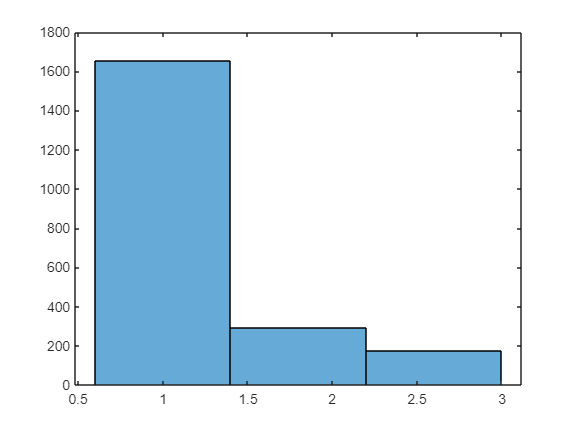

figure
histogram(data.NSP, 3)

[treningInd, testInd, valInd] = dividerand(height(data), 0.7, 0.15, 0.15);

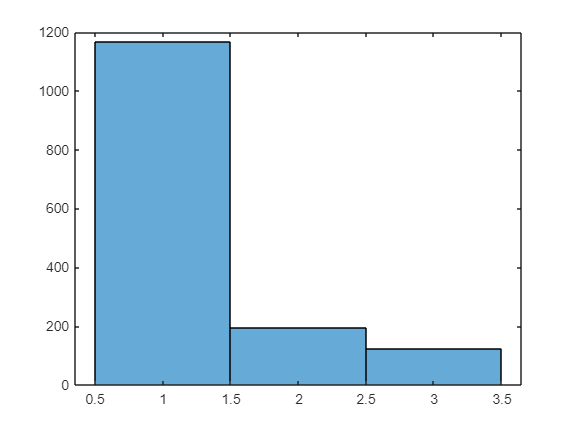

figure
histogram(data(treningInd,:).NSP)

ulaz = data

ulaz = 2126×25 table
      LBE          LB          AC          FM          UC        ASTV        MSTV      ALTV      MLTV          DL          DS        DP    DR     Width       Min         Max         Nmax      Nzeros      Mode        Mean       Median     Variance    Tendency    D    NSP
    ________    ________    ________    ________    ________    _______    ________    ____    _________    ________

ulaz(:, 'NSP') = []

ulaz = 2126×24 table
      LBE          LB          AC          FM          UC        ASTV        MSTV      ALTV      MLTV          DL          DS        DP    DR     Width       Min         Max         Nmax      Nzeros      Mode        Mean       Median     Variance    Tendency    D
    ________    ________    ________    ________    ________    _______    ________    ____    _________    ________    _________

izlaz= data(:, 'NSP')

izlaz = 2126×1 table
    NSP
    ___

     3 
     2 
     1 
     1 
     3 
     2 
     1 
     1 
     1 
     1 
     1 
     1 
     2 
     3 
     2 
     1 


ulaz = ulaz{:,:}'

ulaz =     0.0707    1.7982   -0.3357   -0.3357   -0.9454   -0.1325   -0.1325   -1.3519   -1.8600   -1.9616   -1.1487    2.5096    1.6966    1.4934    1.5950   -0.8438   -0.8438   -0.4373   -0.4373   -1.0471   -1.0471    2.6112    2.5096    2.6112    2.6112    2.1031    0.9853    1.5950    1.4934   -0.8438   -1.0471   -1.0471   -1.1487    0.0707    0.0707   -1.4535   -1.4535   -1.4535   -0.1325    1.6966   -1.3519   -0.8438   -0.6406   -0.6406   -0.4373   -0.6406   -1.0471   -1.2503   -0.8438   -0.8438
    0.0707    1.7982   -0.3357   -0.3357   -0.9454   -0.1325   -0.1325   -1.3519   -1.8600   -1.9616   -1.1487    2.5096    1.6966    1.4934    1.5950   -0.8438   -0.8438   -0.4373   -0.4373   -1.0471   -1.0471    2.6112    2.5096    2.6112    2.6112    2.1031    0.9853    1.5950    1.4934   -0.8438   -1.0471   -1.0471   -1.1487    0.0707    0.0707   -1.4535   -1.4535   -1.4535   -0.1325    1.6966   -1.3519   -0.8438   -0.6406   -0.6406   -0.4373   -0.6406   -1.0471   -1.2503   -0.8438  

izlaz = izlaz{:,:}'

izlaz =      3     2     1     1     3     2     1     1     1     1     1     1     2     3     2     1     1     1     1     1     1     2     1     1     2     1     1     1     1     1     1     1     1     1     1     1     1     1     1     2     1     1     1     1     1     1     1     1     2     2


K1 = ulaz(:, izlaz == 1);
K2 = ulaz(:, izlaz == 2);
K3 = ulaz(:, izlaz == 3);

N1 = length(K1);
K1trening = K1(:, 1 : round(0.7*N1));
K1test = K1(:, round(0.7*N1)+1 : round(0.85*N1));
K1val = K1(:, round(0.85*N1)+1 : N1);

N2 = length(K2);
K2trening = K2(:, 1 : round(0.7*N2));
K2test = K2(:, round(0.7*N2)+1 : round(0.85*N2));
K2val = K2(:, round(0.85*N2)+1 : N2);

N3 = length(K3);
K3trening = K3(:, 1 : round(0.7*N3));
K3test = K3(:, round(0.7*N3)+1 : round(0.85*N3));
K3val = K3(:, round(0.85*N3)+1 : N3);

ulazTrening = [K1trening, K2trening, K3trening];
izTr = [zeros(1, round(0.7*N1))+1, zeros(1, round(0.7*N2))+2, zeros(1, round(0.7*N3))+3];
izlazTrening = zeros (3, length(izTr));
izlazTrening(1, izTr == 1) = 1;
izlazTrening(2, izTr == 2) = 1;
izlazTrening(3, izTr == 3) = 1;

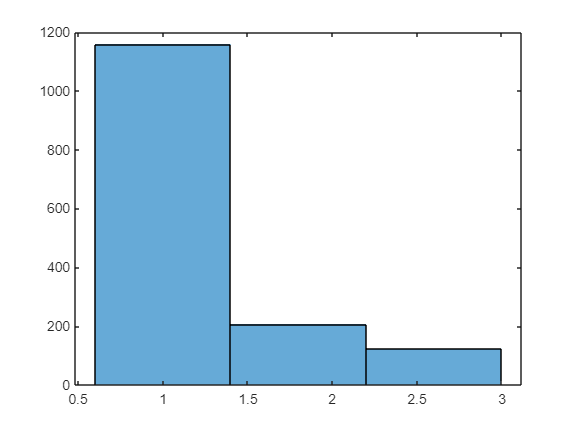

figure
histogram(izTr,3)

ind = randperm(length(izlazTrening));
ulazTrening = ulazTrening(:, ind);
izlazTrening = izlazTrening(:, ind);

D1 = round(0.85*N1) - round(0.7*N1)

D1 = 248

D2 = round(0.85*N2) - round(0.7*N2)

D2 = 44

D3 = round(0.85*N3) - round(0.7*N3)

D3 = 27

ulazTest = [K1test, K2test, K3test];
izTe = [zeros(1, D1)+1, zeros(1, D2)+2, zeros(1, D3)+3];
izlazTest = zeros (3, length(izTe));
izlazTest(1, izTe == 1) = 1;
izlazTest(2, izTe == 2) = 1;
izlazTest(3, izTe == 3) = 1;

DD1 = N1 - round(0.85*N1)

DD1 = 248

DD2 = N2 - round(0.85*N2)

DD2 = 44

DD3 = N3 - round(0.85*N3)

DD3 = 26

ulazVal = [K1val, K2val, K3val];
izVa = [zeros(1, DD1)+1, zeros(1, DD2)+2, zeros(1, DD3)+3];
izlazVal = zeros (3, length(izVa));
izlazVal(1, izVa == 1) = 1;
izlazVal(2, izVa == 2) = 1;
izlazVal(3, izVa == 3) = 1;

ulazNN = [ulazTrening, ulazVal]

ulazNN =     0.0707    0.1724   -1.1487    1.4934   -0.5390    0.2740   -0.2341   -1.0471   -1.3519   -0.5390   -0.5390    0.3756   -1.1487    1.1885   -0.4373   -0.3357   -1.8600    1.1885   -0.5390    1.8999   -0.1325   -1.0471   -0.8438    0.8837    1.0869    0.1724   -1.1487    0.6804   -2.3681    0.6804    1.2901   -1.2503    0.7821    1.4934    0.6804   -0.5390   -0.3357   -0.3357   -0.4373    0.6804   -2.7745    0.8837   -0.2341   -1.6568   -0.3357    0.8837    1.0869   -0.7422    0.4772    0.6804
    0.0707    0.1724   -1.1487    1.4934   -0.5390    0.2740   -0.2341   -1.0471   -1.3519   -0.5390   -0.5390    0.3756   -1.1487    1.1885   -0.4373   -0.3357   -1.8600    1.1885   -0.5390    1.8999   -0.1325   -1.0471   -0.8438    0.8837    1.0869    0.1724   -1.1487    0.6804   -2.3681    0.6804    1.2901   -1.2503    0.7821    1.4934    0.6804   -0.5390   -0.3357   -0.3357   -0.4373    0.6804   -2.7745    0.8837   -0.2341   -1.6568   -0.3357    0.8837    1.0869   -0.7422    0.4772

izlazNN = [izlazTrening, izlazVal]

izlazNN =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     1     1     1     1     0     1     1     0     0     1     1     1     1     1     1     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     1     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0


arhitektura = {[10, 5], [15, 10, 5], [20, 15, 10, 5]};
weights = {[1,2,3], [1,5,10]}
Abest = 0;
F1best = 0;

for reg = [0.1, 0.5, 1.0]
    for w = 1:numel(weights)
        for arh = 1:numel(arhitektura)
            rng(200)
            lr = 1;
            net = patternnet(arhitektura{arh});
            
            for i = 1 : length(arh)
                net.layers{i}.transferFcn = 'tansig';
            end
            net.layers{i+1}.transferFcn = 'softmax';

            net.divideFcn = 'divideind';
            net.divideParam.trainInd = 1 : length(ulazTrening);
            net.divideParam.valInd = length(ulazTrening)+1 : length(ulazSve);
            net.divideParam.testInd = [];

            net.performParam.regularization = reg;

            net.trainFcn = 'trainrp';

            net.trainParam.lr = lr;
            net.trainParam.epochs = 2000;
            net.trainParam.goal = 1e-8;
            net.trainParam.max_fail = 50;
            net.trainParam.showWindow = false;


            [net, info] = train(net, ulazSve, izlazSve, [], [], weights{w},...
                'useParallel', 'yes');

            pred = sim(net, ulazVal);


            [~, cm] = confusion(izlazVal, pred);
            A = 100*sum(trace(cm))/sum(sum(cm));
            TP = trace(cm);
             FP = cm(2,2) + cm(3,3) + cm(2, 1) + cm(2, 3) + cm(3, 1) + cm(3,2);
             precision = TP / (TP+FP);
             recall = TP / (TP+FN);
             F1 = 2 * (precision * recall / (precision + recall));

            disp(['Reg = ' num2str(reg) ', ACC = ' num2str(A) ', F1 = ' num2str(F1)])
            disp(['LR = ' num2str(lr) ', epoch = ' num2str(info.best_epoch)])

            if A > Abest
                F1best = F1;
                Abest = A;
                reg_best = reg;
                w_best = weights{w};
                lr_best = lr;
                arh_best = arhitektura{arh};
                ep_best = info.best_epoch;
            end
        end
      end
    end

ulazNN =     0.0707    0.1724   -1.1487    1.4934   -0.5390    0.2740   -0.2341   -1.0471   -1.3519   -0.5390   -0.5390    0.3756   -1.1487    1.1885   -0.4373   -0.3357   -1.8600    1.1885   -0.5390    1.8999   -0.1325   -1.0471   -0.8438    0.8837    1.0869    0.1724   -1.1487    0.6804   -2.3681    0.6804    1.2901   -1.2503    0.7821    1.4934    0.6804   -0.5390   -0.3357   -0.3357   -0.4373    0.6804   -2.7745    0.8837   -0.2341   -1.6568   -0.3357    0.8837    1.0869   -0.7422    0.4772    0.6804
    0.0707    0.1724   -1.1487    1.4934   -0.5390    0.2740   -0.2341   -1.0471   -1.3519   -0.5390   -0.5390    0.3756   -1.1487    1.1885   -0.4373   -0.3357   -1.8600    1.1885   -0.5390    1.8999   -0.1325   -1.0471   -0.8438    0.8837    1.0869    0.1724   -1.1487    0.6804   -2.3681    0.6804    1.2901   -1.2503    0.7821    1.4934    0.6804   -0.5390   -0.3357   -0.3357   -0.4373    0.6804   -2.7745    0.8837   -0.2341   -1.6568   -0.3357    0.8837    1.0869   -0.7422    0.4772

izlazNN =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     1     1     1     1     0     1     1     0     0     1     1     1     1     1     1     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     1     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0


%%Treniranje NM sa optimalnim parametrima (na celom trening + val skupu)

slojevi3 =     20    10     5


net = patternnet(arh_best);

for i = 1 : length(arh_best)
    net3.layers{i}.transferFcn = 'tansig';
end
net3.layers{i+1}.transferFcn = 'softmax';
net3.divideFcn='';

net.performParam.regularization = reg_best;

net.trainFcn = 'trainrp';

net.trainParam.lr = lr_best;

net.trainParam.epochs = ep_best;
net.trainParam.goal = 1e-5

net =

    Neural Network
 
              name: 'Pattern Recognition Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 4
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 285
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1; 1; 1]
      

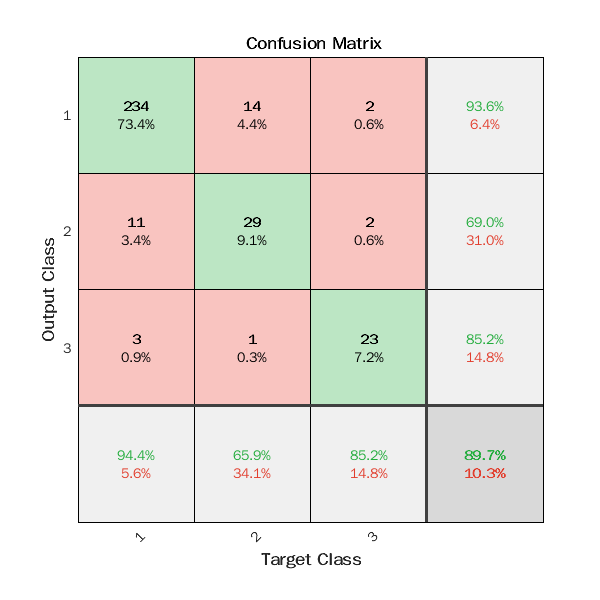



[net, info] = train(net, ulazNN, izlazNN, {}, {}, w_best);

%% Performanse NM
pred = sim(net, ulazTest);
figure, plotconfusion(izlazTest, pred);

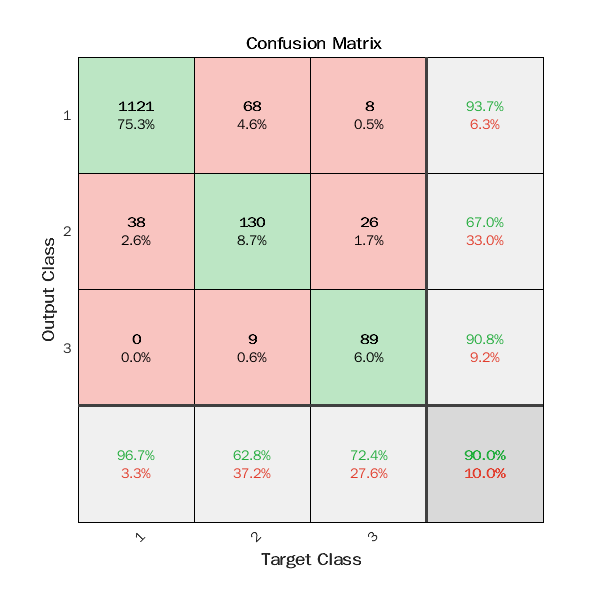

pred1 = sim(net, ulazTrening);
figure, plotconfusion(izlazTrening, pred1);